clear all
clc
T = 50;
numSimulation = 1e5;
format long

# **ASSIGNEMENT DATA**

#### ASSETS

equityPercentage = 0.80;
propertyPercentage = 0.20;
investedPremium = 100000;
equityValue = equityPercentage*investedPremium;
propertyValue = propertyPercentage*investedPremium;
sigmaEquity = 0.20;
sigmaProperty = 0.10;

#### LIABILITIES

penaltyLapse = 20;
RD = 0.0220;
COMM = 0.0140;
pLapse = 0.15;
expensesYear = 50;
inflationRate = 0.02;

# **BASE CASE**

####    TERM STRUCTURE

fileName = 'PROGETTO';
opts = spreadsheetImportOptions('NumVariables',5);
opts.Sheet = 2;
opts.DataRange = 'A4:E54';
opts.VariableNames(1) = {'YEAR'};
opts.VariableNames(2) = {'RATES'};
opts.VariableNames(3) = {'SPOTRATES'};
opts.VariableNames(4) = {'DISCOUNTS'};
opts.VariableNames(5) = {'FORWARD'};
opts = setvartype(opts,'YEAR',{'double'});
opts = setvartype(opts,'RATES',{'double'});
opts = setvartype(opts,'SPOTRATES',{'double'});
opts = setvartype(opts,'DISCOUNTS',{'double'});
opts = setvartype(opts,'FORWARD',{'double'});

temp = readtable(fileName, opts);
years = temp.YEAR;
rates = temp.RATES;
spotRates = temp.SPOTRATES;
discounts = temp.DISCOUNTS;
forward = temp.FORWARD;

#### LIFE TABLE

opts = spreadsheetImportOptions('NumVariables',5);
opts.Sheet = 4;
opts.DataRange = 'A3:E53';
opts.VariableNames(1) = {'AGE'};
opts.VariableNames(2) = {'QXTHOUSEND'};
opts.VariableNames(3) = {'QX'};
opts.VariableNames(4) = {'PX'};
opts.VariableNames(5) = {'PXCUMULATIVE'};
opts = setvartype(opts,'AGE',{'double'});
opts = setvartype(opts,'QXTHOUSEND',{'double'});
opts = setvartype(opts,'QX',{'double'});
opts = setvartype(opts,'PX',{'double'});
opts = setvartype(opts,'PXCUMULATIVE',{'double'});

temp = readtable(fileName, opts);
age = temp.AGE;
qx = temp.QX;
px = temp.PX;
pxCumulative = temp.PXCUMULATIVE;

#### SIMULATION

equityEvolution = computeEquity(T, equityValue, forward, RD, numSimulation, sigmaEquity);
propertyEvolution = computeEquity(T, propertyValue, forward, RD, numSimulation, sigmaProperty);
fundEvolution = equityEvolution + propertyEvolution;

#### PROBABILITIES

lapse = lapseProbabilities(T, px, pLapse, pxCumulative, years);
death = deathProbabilities(T, qx, pLapse, pxCumulative, years);
in = inProbabilities(T, qx, pLapse, pxCumulative, years);

#### BENEFITS

benefitsLapse = lapseBenefits(lapse, fundEvolution, penaltyLapse, discounts);
benefitsDeath = deathBenefits(death, fundEvolution, investedPremium, discounts);

#### OTHER

expensesYearEvolution = computeExpenses(T, expensesYear, inflationRate);

#### LIABILITIES

[lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities] = computeLiabilities(T, numSimulation, benefitsLapse, benefitsDeath, fundEvolution, RD, COMM, in, discounts, expensesYearEvolution);
BEL = sum([lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities]);
totalLiabilities = sum(BEL)

totalLiabilities =      9.567671752316522e+04


#### BOF

BOF_BASE_CASE = computeBOF(lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities, investedPremium)

BOF_BASE_CASE =      4.323282476834778e+03


DURATION_BASE_CASE = computeDuration(years, lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities, totalLiabilities)

DURATION_BASE_CASE =    4.752315919869526


#### PLOT

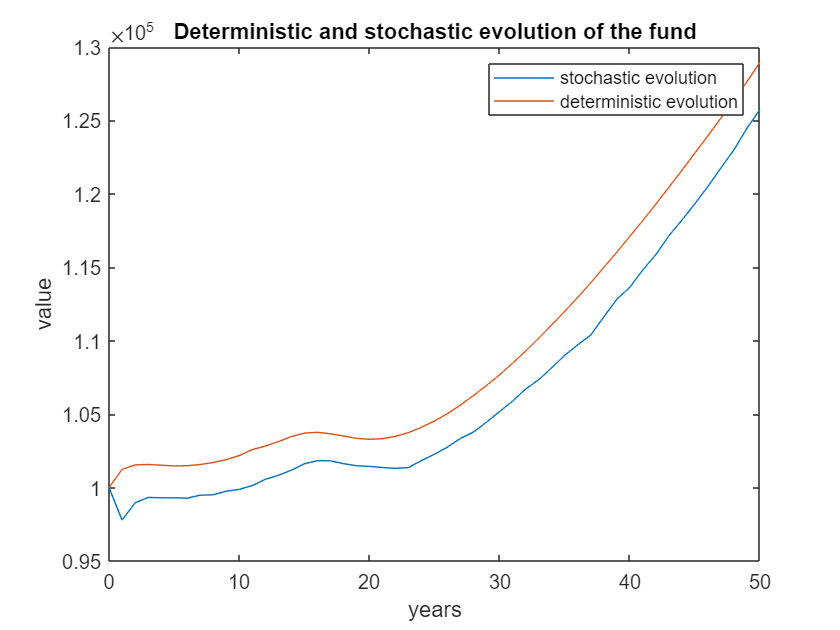

opts = spreadsheetImportOptions('NumVariables',1);
opts.Sheet = 5;
opts.DataRange = 'R3:R53';
opts.VariableNames(1) = {'FUND'};
opts = setvartype(opts,'FUND',{'double'});
temp = readtable(fileName, opts);
fundEvolotuionDeterministic = temp.FUND;

fg = figure(1);
clf(fg)
hold off
plot(years, mean(fundEvolution, 2));
hold on
plot(years, fundEvolotuionDeterministic)
legend('stochastic evolution', 'deterministic evolution')
title('Deterministic and stochastic evolution of the fund')
xlabel('years')
ylabel('value')

# **RATES SHOCK UP**

####    TERM STRUCTURE

fileName = 'PROGETTO';
opts = spreadsheetImportOptions('NumVariables',5);
opts.Sheet = 2;
opts.DataRange = 'G4:K54';
opts.VariableNames(1) = {'YEAR'};
opts.VariableNames(2) = {'RATES'};
opts.VariableNames(3) = {'SPOTRATES'};
opts.VariableNames(4) = {'DISCOUNTS'};
opts.VariableNames(5) = {'FORWARD'};
opts = setvartype(opts,'YEAR',{'double'});
opts = setvartype(opts,'RATES',{'double'});
opts = setvartype(opts,'SPOTRATES',{'double'});
opts = setvartype(opts,'DISCOUNTS',{'double'});
opts = setvartype(opts,'FORWARD',{'double'});

temp = readtable(fileName, opts);
years = temp.YEAR;
rates = temp.RATES;
spotRates = temp.SPOTRATES;
discounts = temp.DISCOUNTS;
forward = temp.FORWARD;

#### LIFE TABLE

opts = spreadsheetImportOptions('NumVariables',5);
opts.Sheet = 4;
opts.DataRange = 'A3:E53';
opts.VariableNames(1) = {'AGE'};
opts.VariableNames(2) = {'QXTHOUSEND'};
opts.VariableNames(3) = {'QX'};
opts.VariableNames(4) = {'PX'};
opts.VariableNames(5) = {'PXCUMULATIVE'};
opts = setvartype(opts,'AGE',{'double'});
opts = setvartype(opts,'QXTHOUSEND',{'double'});
opts = setvartype(opts,'QX',{'double'});
opts = setvartype(opts,'PX',{'double'});
opts = setvartype(opts,'PXCUMULATIVE',{'double'});

temp = readtable(fileName, opts);
age = temp.AGE;
qx = temp.QX;
px = temp.PX;
pxCumulative = temp.PXCUMULATIVE;

#### SIMULATION

equityEvolution = computeEquity(T, equityValue, forward, RD, numSimulation, sigmaEquity);
propertyEvolution = computeEquity(T, propertyValue, forward, RD, numSimulation, sigmaProperty);
fundEvolution = equityEvolution + propertyEvolution;

#### PROBABILITIES

lapse = lapseProbabilities(T, px, pLapse, pxCumulative, years);
death = deathProbabilities(T, qx, pLapse, pxCumulative, years);
in = inProbabilities(T, qx, pLapse, pxCumulative, years);

#### BENEFITS

benefitsLapse = lapseBenefits(lapse, fundEvolution, penaltyLapse, discounts);
benefitsDeath = deathBenefits(death, fundEvolution, investedPremium, discounts);

#### OTHER

expensesYearEvolution = computeExpenses(T, expensesYear, inflationRate);

#### LIABILITIES

[lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities] = computeLiabilities(T, numSimulation, benefitsLapse, benefitsDeath, fundEvolution, RD, COMM, in, discounts, expensesYearEvolution);
BEL = sum([lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities]);
totalLiabilities = sum(BEL)

totalLiabilities =      9.442199771239639e+04


#### BOF

BOF_SHOCK_UP = computeBOF(lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities, investedPremium)

BOF_SHOCK_UP =      5.578002287603609e+03


dBOF_SHOCK_UP = max(BOF_BASE_CASE - BOF_SHOCK_UP, 0)

dBOF_SHOCK_UP =      0


DURATION_SHOCK_UP = computeDuration(years, lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities, totalLiabilities)

DURATION_SHOCK_UP =    4.730445241342858


# **RATES SHOCK DOWN**

####    TERM STRUCTURE

fileName = 'PROGETTO';
opts = spreadsheetImportOptions('NumVariables',5);
opts.Sheet = 2;
opts.DataRange = 'M4:Q54';
opts.VariableNames(1) = {'YEAR'};
opts.VariableNames(2) = {'RATES'};
opts.VariableNames(3) = {'SPOTRATES'};
opts.VariableNames(4) = {'DISCOUNTS'};
opts.VariableNames(5) = {'FORWARD'};
opts = setvartype(opts,'YEAR',{'double'});
opts = setvartype(opts,'RATES',{'double'});
opts = setvartype(opts,'SPOTRATES',{'double'});
opts = setvartype(opts,'DISCOUNTS',{'double'});
opts = setvartype(opts,'FORWARD',{'double'});

temp = readtable(fileName, opts);
years = temp.YEAR;
rates = temp.RATES;
spotRates = temp.SPOTRATES;
discounts = temp.DISCOUNTS;
forward = temp.FORWARD;

#### LIFE TABLE

opts = spreadsheetImportOptions('NumVariables',5);
opts.Sheet = 4;
opts.DataRange = 'A3:E53';
opts.VariableNames(1) = {'AGE'};
opts.VariableNames(2) = {'QXTHOUSEND'};
opts.VariableNames(3) = {'QX'};
opts.VariableNames(4) = {'PX'};
opts.VariableNames(5) = {'PXCUMULATIVE'};
opts = setvartype(opts,'AGE',{'double'});
opts = setvartype(opts,'QXTHOUSEND',{'double'});
opts = setvartype(opts,'QX',{'double'});
opts = setvartype(opts,'PX',{'double'});
opts = setvartype(opts,'PXCUMULATIVE',{'double'});

temp = readtable(fileName, opts);
age = temp.AGE;
qx = temp.QX;
px = temp.PX;
pxCumulative = temp.PXCUMULATIVE;

#### SIMULATION

equityEvolution = computeEquity(T, equityValue, forward, RD, numSimulation, sigmaEquity);
propertyEvolution = computeEquity(T, propertyValue, forward, RD, numSimulation, sigmaProperty);
fundEvolution = equityEvolution + propertyEvolution;

#### PROBABILITIES

lapse = lapseProbabilities(T, px, pLapse, pxCumulative, years);
death = deathProbabilities(T, qx, pLapse, pxCumulative, years);
in = inProbabilities(T, qx, pLapse, pxCumulative, years);

#### BENEFITS

benefitsLapse = lapseBenefits(lapse, fundEvolution, penaltyLapse, discounts);
benefitsDeath = deathBenefits(death, fundEvolution, investedPremium, discounts);

#### OTHER

expensesYearEvolution = computeExpenses(T, expensesYear, inflationRate);

#### LIABILITIES

[lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities] = computeLiabilities(T, numSimulation, benefitsLapse, benefitsDeath, fundEvolution, RD, COMM, in, discounts, expensesYearEvolution);
BEL = sum([lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities]);
totalLiabilities = sum(BEL)

totalLiabilities =      9.674593367736248e+04


#### BOF

BOF_SHOCK_DOWN = computeBOF(lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities, investedPremium)

BOF_SHOCK_DOWN =      3.254066322637518e+03


dBOF_SHOCK_DOWN = max(BOF_BASE_CASE - BOF_SHOCK_DOWN, 0)

dBOF_SHOCK_DOWN =      1.069216154197260e+03


DURATION_SHOCK_DOWN = computeDuration(years, lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities, totalLiabilities)

DURATION_SHOCK_DOWN =    4.766851262559851


# **EQUITY SHOCK**

#### ASSETS

shock = 0.39;
symmetricAdjustment = 0.0525;
equityShocked = equityValue*(1-shock-symmetricAdjustment);
investedPremiumShocked = propertyValue + equityShocked;

####    TERM STRUCTURE

fileName = 'PROGETTO';
opts = spreadsheetImportOptions('NumVariables',5);
opts.Sheet = 2;
opts.DataRange = 'A4:E54';
opts.VariableNames(1) = {'YEAR'};
opts.VariableNames(2) = {'RATES'};
opts.VariableNames(3) = {'SPOTRATES'};
opts.VariableNames(4) = {'DISCOUNTS'};
opts.VariableNames(5) = {'FORWARD'};
opts = setvartype(opts,'YEAR',{'double'});
opts = setvartype(opts,'RATES',{'double'});
opts = setvartype(opts,'SPOTRATES',{'double'});
opts = setvartype(opts,'DISCOUNTS',{'double'});
opts = setvartype(opts,'FORWARD',{'double'});

temp = readtable(fileName, opts);
years = temp.YEAR;
rates = temp.RATES;
spotRates = temp.SPOTRATES;
discounts = temp.DISCOUNTS;
forward = temp.FORWARD;

#### LIFE TABLE

opts = spreadsheetImportOptions('NumVariables',5);
opts.Sheet = 4;
opts.DataRange = 'A3:E53';
opts.VariableNames(1) = {'AGE'};
opts.VariableNames(2) = {'QXTHOUSEND'};
opts.VariableNames(3) = {'QX'};
opts.VariableNames(4) = {'PX'};
opts.VariableNames(5) = {'PXCUMULATIVE'};
opts = setvartype(opts,'AGE',{'double'});
opts = setvartype(opts,'QXTHOUSEND',{'double'});
opts = setvartype(opts,'QX',{'double'});
opts = setvartype(opts,'PX',{'double'});
opts = setvartype(opts,'PXCUMULATIVE',{'double'});

temp = readtable(fileName, opts);
age = temp.AGE;
qx = temp.QX;
px = temp.PX;
pxCumulative = temp.PXCUMULATIVE;

#### SIMULATION

equityEvolution = computeEquity(T, equityShocked, forward, RD, numSimulation, sigmaEquity);
propertyEvolution = computeProperty(T, propertyValue, forward, RD, numSimulation, sigmaProperty);
fundEvolution = equityEvolution + propertyEvolution;

#### PROBABILITIES

lapse = lapseProbabilities(T, px, pLapse, pxCumulative, years);
death = deathProbabilities(T, qx, pLapse, pxCumulative, years);
in = inProbabilities(T, qx, pLapse, pxCumulative, years);

#### BENEFITS

benefitsLapse = lapseBenefits(lapse, fundEvolution, penaltyLapse, discounts);
benefitsDeath = deathBenefits(death, fundEvolution, investedPremium, discounts);

#### OTHER

expensesYearEvolution = computeExpenses(T, expensesYear, inflationRate);

#### LIABILITIES

[lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities] = computeLiabilities(T, numSimulation, benefitsLapse, benefitsDeath, fundEvolution, RD, COMM, in, discounts, expensesYearEvolution);
BEL = sum([lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities]);
totalLiabilities = sum(BEL)

totalLiabilities =      6.371423037116963e+04


#### BOF

BOF_EQUITY = computeBOF(lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities, investedPremiumShocked)

BOF_EQUITY =      8.857696288303705e+02


dBOF_EQUITY = max(BOF_BASE_CASE - BOF_EQUITY, 0)

dBOF_EQUITY =      3.437512848004408e+03


DURATION_EQUITY = computeDuration(years, lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities, totalLiabilities)

DURATION_EQUITY =    4.824367307959890


# **PROPERTY SHOCK**

#### ASSETS

shock = 0.25;
propertyShocked = propertyValue*(1-shock);
investedPremiumShocked = propertyShocked + equityValue;

####    TERM STRUCTURE

fileName = 'PROGETTO';
opts = spreadsheetImportOptions('NumVariables',5);
opts.Sheet = 2;
opts.DataRange = 'A4:E54';
opts.VariableNames(1) = {'YEAR'};
opts.VariableNames(2) = {'RATES'};
opts.VariableNames(3) = {'SPOTRATES'};
opts.VariableNames(4) = {'DISCOUNTS'};
opts.VariableNames(5) = {'FORWARD'};
opts = setvartype(opts,'YEAR',{'double'});
opts = setvartype(opts,'RATES',{'double'});
opts = setvartype(opts,'SPOTRATES',{'double'});
opts = setvartype(opts,'DISCOUNTS',{'double'});
opts = setvartype(opts,'FORWARD',{'double'});

temp = readtable(fileName, opts);
years = temp.YEAR;
rates = temp.RATES;
spotRates = temp.SPOTRATES;
discounts = temp.DISCOUNTS;
forward = temp.FORWARD;

#### LIFE TABLE

opts = spreadsheetImportOptions('NumVariables',5);
opts.Sheet = 4;
opts.DataRange = 'A3:E53';
opts.VariableNames(1) = {'AGE'};
opts.VariableNames(2) = {'QXTHOUSEND'};
opts.VariableNames(3) = {'QX'};
opts.VariableNames(4) = {'PX'};
opts.VariableNames(5) = {'PXCUMULATIVE'};
opts = setvartype(opts,'AGE',{'double'});
opts = setvartype(opts,'QXTHOUSEND',{'double'});
opts = setvartype(opts,'QX',{'double'});
opts = setvartype(opts,'PX',{'double'});
opts = setvartype(opts,'PXCUMULATIVE',{'double'});

temp = readtable(fileName, opts);
age = temp.AGE;
qx = temp.QX;
px = temp.PX;
pxCumulative = temp.PXCUMULATIVE;

#### SIMULATION

equityEvolution = computeEquity(T, equityValue, forward, RD, numSimulation, sigmaEquity);
propertyEvolution = computeEquity(T, propertyShocked, forward, RD, numSimulation, sigmaProperty);
fundEvolution = equityEvolution + propertyEvolution;

#### PROBABILITIES

lapse = lapseProbabilities(T, px, pLapse, pxCumulative, years);
death = deathProbabilities(T, qx, pLapse, pxCumulative, years);
in = inProbabilities(T, qx, pLapse, pxCumulative, years);

#### BENEFITS

benefitsLapse = lapseBenefits(lapse, fundEvolution, penaltyLapse, discounts);
benefitsDeath = deathBenefits(death, fundEvolution, investedPremium, discounts);

#### OTHER

expensesYearEvolution = computeExpenses(T, expensesYear, inflationRate);

#### LIABILITIES

[lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities] = computeLiabilities(T, numSimulation, benefitsLapse, benefitsDeath, fundEvolution, RD, COMM, in, discounts, expensesYearEvolution);
BEL = sum([lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities]);
totalLiabilities = sum(BEL)

totalLiabilities =      9.114912357424495e+04


#### BOF

BOF_PROPERTY = computeBOF(lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities, investedPremiumShocked)

BOF_PROPERTY =      3.850876425755050e+03


dBOF_PROPERTY = max(BOF_BASE_CASE - BOF_PROPERTY, 0)

dBOF_PROPERTY =      4.724060510797281e+02


DURATION_PROPERTY = computeDuration(years, lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities, totalLiabilities)

DURATION_PROPERTY =    4.761088555568814


# **MORTALITY SHOCK**

####    TERM STRUCTURE

fileName = 'PROGETTO';
opts = spreadsheetImportOptions('NumVariables',5);
opts.Sheet = 2;
opts.DataRange = 'A4:E54';
opts.VariableNames(1) = {'YEAR'};
opts.VariableNames(2) = {'RATES'};
opts.VariableNames(3) = {'SPOTRATES'};
opts.VariableNames(4) = {'DISCOUNTS'};
opts.VariableNames(5) = {'FORWARD'};
opts = setvartype(opts,'YEAR',{'double'});
opts = setvartype(opts,'RATES',{'double'});
opts = setvartype(opts,'SPOTRATES',{'double'});
opts = setvartype(opts,'DISCOUNTS',{'double'});
opts = setvartype(opts,'FORWARD',{'double'});

temp = readtable(fileName, opts);
years = temp.YEAR;
rates = temp.RATES;
spotRates = temp.SPOTRATES;
discounts = temp.DISCOUNTS;
forward = temp.FORWARD;

#### LIFE TABLE

opts = spreadsheetImportOptions('NumVariables',5);
opts.Sheet = 4;
opts.DataRange = 'G3:K53';
opts.VariableNames(1) = {'AGE'};
opts.VariableNames(2) = {'QXTHOUSEND'};
opts.VariableNames(3) = {'QX'};
opts.VariableNames(4) = {'PX'};
opts.VariableNames(5) = {'PXCUMULATIVE'};
opts = setvartype(opts,'AGE',{'double'});
opts = setvartype(opts,'QXTHOUSEND',{'double'});
opts = setvartype(opts,'QX',{'double'});
opts = setvartype(opts,'PX',{'double'});
opts = setvartype(opts,'PXCUMULATIVE',{'double'});

temp = readtable(fileName, opts);
age = temp.AGE;
qx = temp.QX;
px = temp.PX;
pxCumulative = temp.PXCUMULATIVE;

#### SIMULATION

equityEvolution = computeEquity(T, equityValue, forward, RD, numSimulation, sigmaEquity);
propertyEvolution = computeEquity(T, propertyValue, forward, RD, numSimulation, sigmaProperty);
fundEvolution = equityEvolution + propertyEvolution;

#### PROBABILITIES

lapse = lapseProbabilities(T, px, pLapse, pxCumulative, years);
death = deathProbabilities(T, qx, pLapse, pxCumulative, years);
in = inProbabilities(T, qx, pLapse, pxCumulative, years);

#### BENEFITS

benefitsLapse = lapseBenefits(lapse, fundEvolution, penaltyLapse, discounts);
benefitsDeath = deathBenefits(death, fundEvolution, investedPremium, discounts);

#### OTHER

expensesYearEvolution = computeExpenses(T, expensesYear, inflationRate);

#### LIABILITIES

[lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities] = computeLiabilities(T, numSimulation, benefitsLapse, benefitsDeath, fundEvolution, RD, COMM, in, discounts, expensesYearEvolution);
BEL = sum([lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities]);
totalLiabilities = sum(BEL)

totalLiabilities =      9.583467693321490e+04


#### BOF

BOF_MORTALITY = computeBOF(lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities, investedPremium)

BOF_MORTALITY =      4.165323066785102e+03


dBOF_MORTALITY = max(BOF_BASE_CASE - BOF_MORTALITY, 0)

dBOF_MORTALITY =      1.579594100496761e+02


DURATION_MORTALITY = computeDuration(years, lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities, totalLiabilities)

DURATION_MORTALITY =    4.716184813935210


# **LAPSE SHOCK UP**

#### LIABILITIES

shock = 1.5;
lapseShocked = min(pLapse*shock, 1);

####    TERM STRUCTURE

fileName = 'PROGETTO';
opts = spreadsheetImportOptions('NumVariables',5);
opts.Sheet = 2;
opts.DataRange = 'A4:E54';
opts.VariableNames(1) = {'YEAR'};
opts.VariableNames(2) = {'RATES'};
opts.VariableNames(3) = {'SPOTRATES'};
opts.VariableNames(4) = {'DISCOUNTS'};
opts.VariableNames(5) = {'FORWARD'};
opts = setvartype(opts,'YEAR',{'double'});
opts = setvartype(opts,'RATES',{'double'});
opts = setvartype(opts,'SPOTRATES',{'double'});
opts = setvartype(opts,'DISCOUNTS',{'double'});
opts = setvartype(opts,'FORWARD',{'double'});

temp = readtable(fileName, opts);
years = temp.YEAR;
rates = temp.RATES;
spotRates = temp.SPOTRATES;
discounts = temp.DISCOUNTS;
forward = temp.FORWARD;

#### LIFE TABLE

opts = spreadsheetImportOptions('NumVariables',5);
opts.Sheet = 4;
opts.DataRange = 'A3:E53';
opts.VariableNames(1) = {'AGE'};
opts.VariableNames(2) = {'QXTHOUSEND'};
opts.VariableNames(3) = {'QX'};
opts.VariableNames(4) = {'PX'};
opts.VariableNames(5) = {'PXCUMULATIVE'};
opts = setvartype(opts,'AGE',{'double'});
opts = setvartype(opts,'QXTHOUSEND',{'double'});
opts = setvartype(opts,'QX',{'double'});
opts = setvartype(opts,'PX',{'double'});
opts = setvartype(opts,'PXCUMULATIVE',{'double'});

temp = readtable(fileName, opts);
age = temp.AGE;
qx = temp.QX;
px = temp.PX;
pxCumulative = temp.PXCUMULATIVE;

#### SIMULATION

equityEvolution = computeEquity(T, equityValue, forward, RD, numSimulation, sigmaEquity);
propertyEvolution = computeEquity(T, propertyValue, forward, RD, numSimulation, sigmaProperty);
fundEvolution = equityEvolution + propertyEvolution;

#### PROBABILITIES

lapse = lapseProbabilities(T, px, lapseShocked, pxCumulative, years);
death = deathProbabilities(T, qx, lapseShocked, pxCumulative, years);
in = inProbabilities(T, qx, lapseShocked, pxCumulative, years);

#### BENEFITS

benefitsLapse = lapseBenefits(lapse, fundEvolution, penaltyLapse, discounts);
benefitsDeath = deathBenefits(death, fundEvolution, investedPremium, discounts);

#### OTHER

expensesYearEvolution = computeExpenses(T, expensesYear, inflationRate);

#### LIABILITIES

[lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities] = computeLiabilities(T, numSimulation, benefitsLapse, benefitsDeath, fundEvolution, RD, COMM, in, discounts, expensesYearEvolution);
BEL = sum([lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities]);
totalLiabilities = sum(BEL)

totalLiabilities =      9.630982147063440e+04


#### BOF

BOF_LAPSE_UP = computeBOF(lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities, investedPremium)

BOF_LAPSE_UP =      3.690178529365599e+03


dBOF_LAPSE_UP = max(BOF_BASE_CASE - BOF_LAPSE_UP, 0)

dBOF_LAPSE_UP =      6.331039474691788e+02


DURATION_LAPSE_UP = computeDuration(years, lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities, totalLiabilities)

DURATION_LAPSE_UP =    3.071680259095794


# **LAPSE SHOCK DOWN**

#### LIABILITIES

shock = 0.5;
lapseShocked = max(pLapse*shock, pLapse-0.2);

####    TERM STRUCTURE

fileName = 'PROGETTO';
opts = spreadsheetImportOptions('NumVariables',5);
opts.Sheet = 2;
opts.DataRange = 'A4:E54';
opts.VariableNames(1) = {'YEAR'};
opts.VariableNames(2) = {'RATES'};
opts.VariableNames(3) = {'SPOTRATES'};
opts.VariableNames(4) = {'DISCOUNTS'};
opts.VariableNames(5) = {'FORWARD'};
opts = setvartype(opts,'YEAR',{'double'});
opts = setvartype(opts,'RATES',{'double'});
opts = setvartype(opts,'SPOTRATES',{'double'});
opts = setvartype(opts,'DISCOUNTS',{'double'});
opts = setvartype(opts,'FORWARD',{'double'});

temp = readtable(fileName, opts);
years = temp.YEAR;
rates = temp.RATES;
spotRates = temp.SPOTRATES;
discounts = temp.DISCOUNTS;
forward = temp.FORWARD;

#### LIFE TABLE

opts = spreadsheetImportOptions('NumVariables',5);
opts.Sheet = 4;
opts.DataRange = 'A3:E53';
opts.VariableNames(1) = {'AGE'};
opts.VariableNames(2) = {'QXTHOUSEND'};
opts.VariableNames(3) = {'QX'};
opts.VariableNames(4) = {'PX'};
opts.VariableNames(5) = {'PXCUMULATIVE'};
opts = setvartype(opts,'AGE',{'double'});
opts = setvartype(opts,'QXTHOUSEND',{'double'});
opts = setvartype(opts,'QX',{'double'});
opts = setvartype(opts,'PX',{'double'});
opts = setvartype(opts,'PXCUMULATIVE',{'double'});

temp = readtable(fileName, opts);
age = temp.AGE;
qx = temp.QX;
px = temp.PX;
pxCumulative = temp.PXCUMULATIVE;

#### SIMULATION

equityEvolution = computeEquity(T, equityValue, forward, RD, numSimulation, sigmaEquity);
propertyEvolution = computeEquity(T, propertyValue, forward, RD, numSimulation, sigmaProperty);
fundEvolution = equityEvolution + propertyEvolution;

#### PROBABILITIES

lapse = lapseProbabilities(T, px, lapseShocked, pxCumulative, years);
death = deathProbabilities(T, qx, lapseShocked, pxCumulative, years);
in = inProbabilities(T, qx, lapseShocked, pxCumulative, years);

#### BENEFITS

benefitsLapse = lapseBenefits(lapse, fundEvolution, penaltyLapse, discounts);
benefitsDeath = deathBenefits(death, fundEvolution, investedPremium, discounts);

#### OTHER

expensesYearEvolution = computeExpenses(T, expensesYear, inflationRate);

#### LIABILITIES

[lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities] = computeLiabilities(T, numSimulation, benefitsLapse, benefitsDeath, fundEvolution, RD, COMM, in, discounts, expensesYearEvolution);
BEL = sum([lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities]);
totalLiabilities = sum(BEL)

totalLiabilities =      9.568155139435884e+04


#### BOF

BOF_LAPSE_DOWN = computeBOF(lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities, investedPremium)

BOF_LAPSE_DOWN =      4.318448605641155e+03


dBOF_LAPSE_DOWN = max(BOF_BASE_CASE - BOF_LAPSE_DOWN, 0)

dBOF_LAPSE_DOWN =    4.833871193623054


DURATION_LAPSE_DOWN = computeDuration(years, lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities, totalLiabilities)

DURATION_LAPSE_DOWN =    8.493178213657531


# **LAPSE SHOCK MASS**

#### LIABILITIES

shock = 0.4;
lapseShocked = pLapse+shock;

#### TERM STRUCTURE

fileName = 'PROGETTO';
opts = spreadsheetImportOptions('NumVariables',5);
opts.Sheet = 2;
opts.DataRange = 'A4:E54';
opts.VariableNames(1) = {'YEAR'};
opts.VariableNames(2) = {'RATES'};
opts.VariableNames(3) = {'SPOTRATES'};
opts.VariableNames(4) = {'DISCOUNTS'};
opts.VariableNames(5) = {'FORWARD'};
opts = setvartype(opts,'YEAR',{'double'});
opts = setvartype(opts,'RATES',{'double'});
opts = setvartype(opts,'SPOTRATES',{'double'});
opts = setvartype(opts,'DISCOUNTS',{'double'});
opts = setvartype(opts,'FORWARD',{'double'});

temp = readtable(fileName, opts);
years = temp.YEAR;
rates = temp.RATES;
spotRates = temp.SPOTRATES;
discounts = temp.DISCOUNTS;
forward = temp.FORWARD;

#### LIFE TABLE

opts = spreadsheetImportOptions('NumVariables',5);
opts.Sheet = 4;
opts.DataRange = 'A3:E53';
opts.VariableNames(1) = {'AGE'};
opts.VariableNames(2) = {'QXTHOUSEND'};
opts.VariableNames(3) = {'QX'};
opts.VariableNames(4) = {'PX'};
opts.VariableNames(5) = {'PXCUMULATIVE'};
opts = setvartype(opts,'AGE',{'double'});
opts = setvartype(opts,'QXTHOUSEND',{'double'});
opts = setvartype(opts,'QX',{'double'});
opts = setvartype(opts,'PX',{'double'});
opts = setvartype(opts,'PXCUMULATIVE',{'double'});

temp = readtable(fileName, opts);
age = temp.AGE;
qx = temp.QX;
px = temp.PX;
pxCumulative = temp.PXCUMULATIVE;

#### SIMULATION

equityEvolution = computeEquity(T, equityValue, forward, RD, numSimulation, sigmaEquity);
propertyEvolution = computeEquity(T, propertyValue, forward, RD, numSimulation, sigmaProperty);
fundEvolution = equityEvolution + propertyEvolution;

#### PROBABILITIES

lapse = zeros(T+1,1);
lapse(1) = px(1)*lapseShocked;
lapse(2:end) = pxCumulative(1:end-1).*px(2:end).*(1-pLapse).^(years(2:end)-1).*pLapse.*(1-lapseShocked);

death = zeros(51,1);
death(1) = qx(1);
death(2:end) = pxCumulative(1:end-1).*qx(2:end).*(1-pLapse).^(years(2:end)-1).*(1-lapseShocked);

in = zeros(T+1,1);
in(1) = (1-qx(1))*(1-lapseShocked);
for i = 2:T+1
    in(i) = in(i-1)*(1-qx(i))*(1-pLapse);
end

#### BENEFITS

benefitsLapse = lapseBenefits(lapse, fundEvolution, penaltyLapse, discounts);
benefitsDeath = deathBenefits(death, fundEvolution, investedPremium, discounts);

#### OTHER

expensesYearEvolution = computeExpenses(T, expensesYear, inflationRate);

#### LIABILITIES

[lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities] = computeLiabilities(T, numSimulation, benefitsLapse, benefitsDeath, fundEvolution, RD, COMM, in, discounts, expensesYearEvolution);
BEL = sum([lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities]);
totalLiabilities = sum(BEL)

totalLiabilities =      9.772538191574607e+04


#### BOF

BOF_LAPSE_MASS = computeBOF(lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities, investedPremium)

BOF_LAPSE_MASS =      2.274618084253932e+03


dBOF_LAPSE_MASS = max(BOF_BASE_CASE - BOF_LAPSE_MASS, 0)

dBOF_LAPSE_MASS =      2.048664392580846e+03


DURATION_LAPSE_MASS = computeDuration(years, lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities, totalLiabilities)

DURATION_LAPSE_MASS =    2.463189260495559


# **CATASTROPHE**

####    TERM STRUCTURE

fileName = 'PROGETTO';
opts = spreadsheetImportOptions('NumVariables',5);
opts.Sheet = 2;
opts.DataRange = 'A4:E54';
opts.VariableNames(1) = {'YEAR'};
opts.VariableNames(2) = {'RATES'};
opts.VariableNames(3) = {'SPOTRATES'};
opts.VariableNames(4) = {'DISCOUNTS'};
opts.VariableNames(5) = {'FORWARD'};
opts = setvartype(opts,'YEAR',{'double'});
opts = setvartype(opts,'RATES',{'double'});
opts = setvartype(opts,'SPOTRATES',{'double'});
opts = setvartype(opts,'DISCOUNTS',{'double'});
opts = setvartype(opts,'FORWARD',{'double'});

temp = readtable(fileName, opts);
years = temp.YEAR;
rates = temp.RATES;
spotRates = temp.SPOTRATES;
discounts = temp.DISCOUNTS;
forward = temp.FORWARD;

#### LIFE TABLE

opts = spreadsheetImportOptions('NumVariables',5);
opts.Sheet = 4;
opts.DataRange = 'N3:R53';
opts.VariableNames(1) = {'AGE'};
opts.VariableNames(2) = {'QXTHOUSEND'};
opts.VariableNames(3) = {'QX'};
opts.VariableNames(4) = {'PX'};
opts.VariableNames(5) = {'PXCUMULATIVE'};
opts = setvartype(opts,'AGE',{'double'});
opts = setvartype(opts,'QXTHOUSEND',{'double'});
opts = setvartype(opts,'QX',{'double'});
opts = setvartype(opts,'PX',{'double'});
opts = setvartype(opts,'PXCUMULATIVE',{'double'});

temp = readtable(fileName, opts);
age = temp.AGE;
qx = temp.QX;
px = temp.PX;
pxCumulative = temp.PXCUMULATIVE;

#### SIMULATION

equityEvolution = computeEquity(T, equityValue, forward, RD, numSimulation, sigmaEquity);
propertyEvolution = computeEquity(T, propertyValue, forward, RD, numSimulation, sigmaProperty);
fundEvolution = equityEvolution + propertyEvolution;

#### PROBABILITIES

lapse = lapseProbabilities(T, px, pLapse, pxCumulative, years);
death = deathProbabilities(T, qx, pLapse, pxCumulative, years);
in = inProbabilities(T, qx, pLapse, pxCumulative, years);

#### BENEFITS

benefitsLapse = lapseBenefits(lapse, fundEvolution, penaltyLapse, discounts);
benefitsDeath = deathBenefits(death, fundEvolution, investedPremium, discounts);

#### OTHER

expensesYearEvolution = computeExpenses(T, expensesYear, inflationRate);

#### LIABILITIES

[lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities] = computeLiabilities(T, numSimulation, benefitsLapse, benefitsDeath, fundEvolution, RD, COMM, in, discounts, expensesYearEvolution);
BEL = sum([lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities]);
totalLiabilities = sum(BEL)

totalLiabilities =      9.568332015182421e+04


#### BOF

BOF_CATASTROPHE = computeBOF(lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities, investedPremium)

BOF_CATASTROPHE =      4.316679848175787e+03


dBOF_CATASTROPHE = max(BOF_BASE_CASE - BOF_CATASTROPHE, 0)

dBOF_CATASTROPHE =    6.602628658991307


DURATION_CATASTROPHE = computeDuration(years, lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities, totalLiabilities)

DURATION_CATASTROPHE =    4.744813601283577


# **EXPENSES**

expensesShock = 0.1;
expensesYearShocked = expensesYear*(1+expensesShock);
inflationShock = 0.01;
inflationRateShocked = inflationRate + inflationShock;

####    TERM STRUCTURE

fileName = 'PROGETTO';
opts = spreadsheetImportOptions('NumVariables',5);
opts.Sheet = 2;
opts.DataRange = 'A4:E54';
opts.VariableNames(1) = {'YEAR'};
opts.VariableNames(2) = {'RATES'};
opts.VariableNames(3) = {'SPOTRATES'};
opts.VariableNames(4) = {'DISCOUNTS'};
opts.VariableNames(5) = {'FORWARD'};
opts = setvartype(opts,'YEAR',{'double'});
opts = setvartype(opts,'RATES',{'double'});
opts = setvartype(opts,'SPOTRATES',{'double'});
opts = setvartype(opts,'DISCOUNTS',{'double'});
opts = setvartype(opts,'FORWARD',{'double'});

temp = readtable(fileName, opts);
years = temp.YEAR;
rates = temp.RATES;
spotRates = temp.SPOTRATES;
discounts = temp.DISCOUNTS;
forward = temp.FORWARD;

#### LIFE TABLE

opts = spreadsheetImportOptions('NumVariables',5);
opts.Sheet = 4;
opts.DataRange = 'A3:E53';
opts.VariableNames(1) = {'AGE'};
opts.VariableNames(2) = {'QXTHOUSEND'};
opts.VariableNames(3) = {'QX'};
opts.VariableNames(4) = {'PX'};
opts.VariableNames(5) = {'PXCUMULATIVE'};
opts = setvartype(opts,'AGE',{'double'});
opts = setvartype(opts,'QXTHOUSEND',{'double'});
opts = setvartype(opts,'QX',{'double'});
opts = setvartype(opts,'PX',{'double'});
opts = setvartype(opts,'PXCUMULATIVE',{'double'});

temp = readtable(fileName, opts);
age = temp.AGE;
qx = temp.QX;
px = temp.PX;
pxCumulative = temp.PXCUMULATIVE;

#### SIMULATION

equityEvolution = computeEquity(T, equityValue, forward, RD, numSimulation, sigmaEquity);
propertyEvolution = computeEquity(T, propertyValue, forward, RD, numSimulation, sigmaProperty);
fundEvolution = equityEvolution + propertyEvolution;

#### PROBABILITIES

lapse = lapseProbabilities(T, px, pLapse, pxCumulative, years);
death = deathProbabilities(T, qx, pLapse, pxCumulative, years);
in = inProbabilities(T, qx, pLapse, pxCumulative, years);

#### BENEFITS

benefitsLapse = lapseBenefits(lapse, fundEvolution, penaltyLapse, discounts);
benefitsDeath = deathBenefits(death, fundEvolution, investedPremium, discounts);

#### OTHER

expensesYearEvolution = computeExpenses(T, expensesYearShocked, inflationRateShocked);

#### LIABILITIES

[lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities] = computeLiabilities(T, numSimulation, benefitsLapse, benefitsDeath, fundEvolution, RD, COMM, in, discounts, expensesYearEvolution);
BEL = sum([lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities]);
totalLiabilities = sum(BEL)

totalLiabilities =      9.572344331922763e+04


#### BOF

BOF_EXPENSES = computeBOF(lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities, investedPremium)

BOF_EXPENSES =      4.276556680772366e+03


dBOF_EXPENSES = max(BOF_BASE_CASE - BOF_EXPENSES, 0)

dBOF_EXPENSES =   46.725796062411973


DURATION_EXPENSES = computeDuration(years, lapseLiabilities, deathLiabilities, commLiabilities, expensesLiabilities, totalLiabilities)

DURATION_EXPENSES =    4.753261744365489


# **BASIC SOLVENCY CAPITAL REQUIREMENT**

#### **MARKET**

if dBOF_SHOCK_UP > dBOF_SHOCK_DOWN
    a = 0;
else
    a = 0.5;
end
marketCorrelationMatrix = [1 a a; a 1 0.75; a 0.75 1];
dBOF_MARKET = max(dBOF_SHOCK_UP, dBOF_SHOCK_DOWN);
marketSCR = [dBOF_MARKET; dBOF_EQUITY; dBOF_PROPERTY];
totalMarket = sqrt(marketSCR'*marketCorrelationMatrix*marketSCR)

totalMarket =      4.449638917404738e+03


#### **LIFE**

lifeCorrelationMatrix = [1 0 0.25 0.25; 0 1 0.5 0.25; 0.25 0.5 1 0.25; 0.25 0.25 0.25 1];
dBOF_LAPSE = max([dBOF_LAPSE_UP; dBOF_LAPSE_DOWN; dBOF_LAPSE_MASS]);
lifeSCR = [dBOF_MORTALITY; dBOF_LAPSE; dBOF_EXPENSES; dBOF_CATASTROPHE];
totalLife = sqrt(lifeSCR'*lifeCorrelationMatrix*lifeSCR)

totalLife =      2.081119588801280e+03


#### TOTAL

totalCorrelationMatrix = [1 0.25; 0.25 1];
totalSCR = [totalMarket; totalLife];
BSCR = sqrt(totalSCR'*totalCorrelationMatrix*totalSCR)

BSCR =      5.362878014203473e+03


# **MARTINGALE TEST**

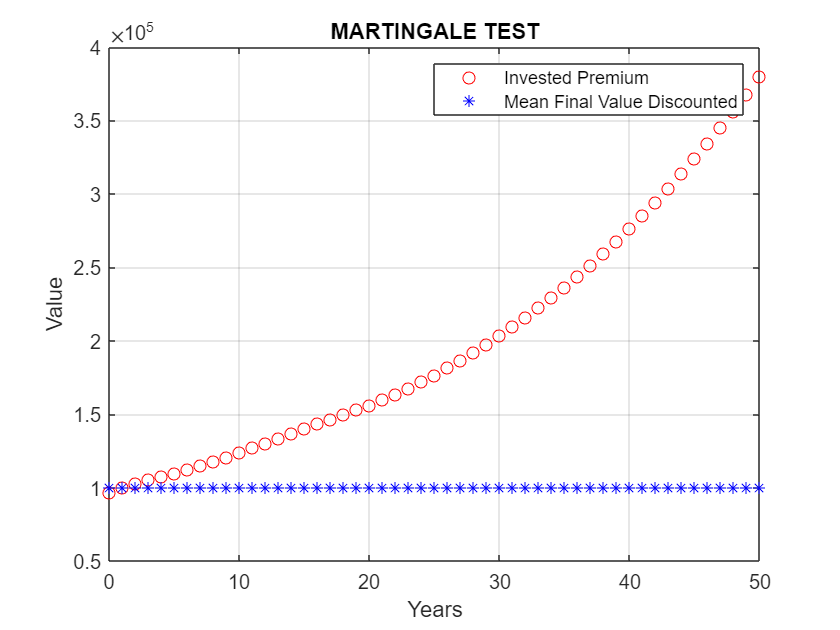

equityEvolutionTest = computeEquity(T, equityValue, forward, 0, numSimulation, sigmaEquity);
propertyEvolutionTest = computeProperty(T, propertyValue, forward, 0, numSimulation, sigmaProperty);
fundEvolutionTest = equityEvolutionTest + propertyEvolutionTest;

meanFundFinal = mean(fundEvolutionTest(T+1, :));
discountsTest = discounts(T+1)./discounts;
meanFundFinalDiscounted = meanFundFinal*discountsTest;

fg = figure(2);
clf(fg)
hold off
plot(years, meanFundFinalDiscounted, 'or')
hold on 
plot(years, investedPremium*ones(T+1), '*b')
grid on
title('MARTINGALE TEST')
legend('Invested Premium', 'Mean Final Value Discounted')
ylabel('Value')
xlabel('Years')

# **NUMBER OF SIMULATIONS**

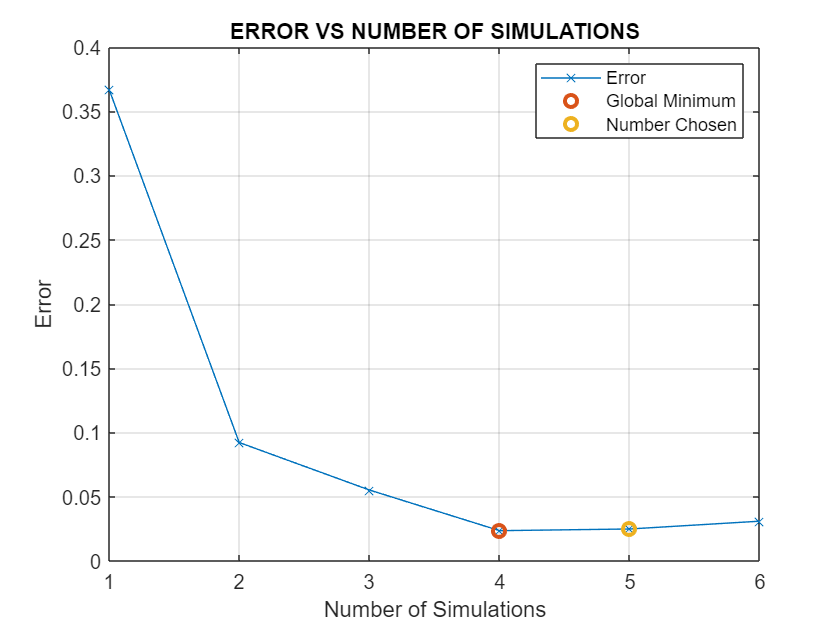

for i = 1:6
    numSimulation = 10^i;
    equityEvolutionTest = computeEquity(T, equityValue, forward, 0, numSimulation, sigmaEquity);
    propertyEvolutionTest = computeProperty(T, propertyValue, forward, 0, numSimulation, sigmaProperty);
    fundEvolutionTest = equityEvolutionTest + propertyEvolutionTest;

    meanFundFinal = mean(fundEvolutionTest(T+1, :));
    discountsTest = discounts(T+1)./discounts;
    meanFundFinalDiscounted = meanFundFinal*discountsTest;
    error(i) = 1 - meanFundFinalDiscounted(1)/investedPremium;
end

fg = figure(3);
clf(fg)
hold off
plot((1:6), error, 'x-')
grid on
hold on
plot(4, error(4), 'o', 'LineWidth', 2)
plot(5, error(5), 'o', 'LineWidth', 2)
title('ERROR VS NUMBER OF SIMULATIONS')
xlabel('Number of Simulations')
ylabel('Error')
legend('Error', 'Global Minimum', 'Number Chosen')